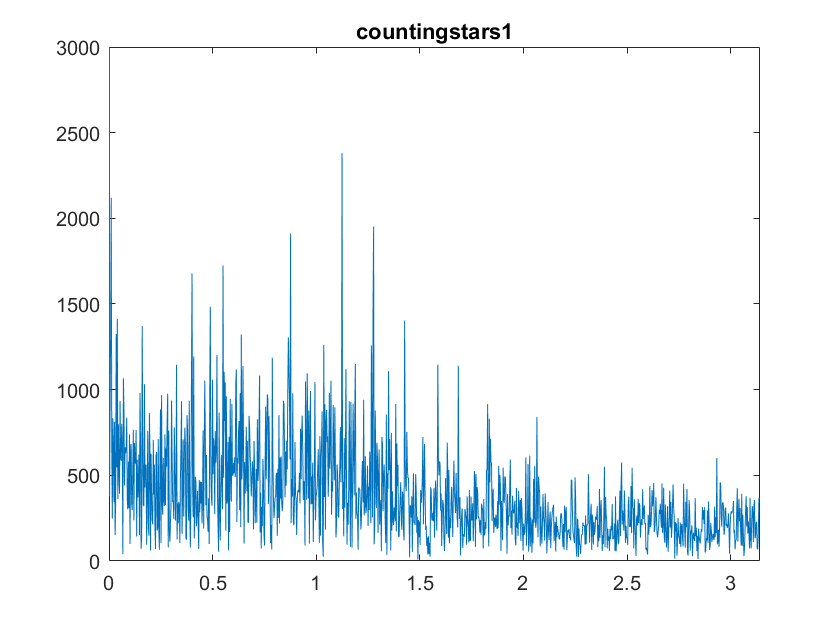

plot_fft("countingstars1");

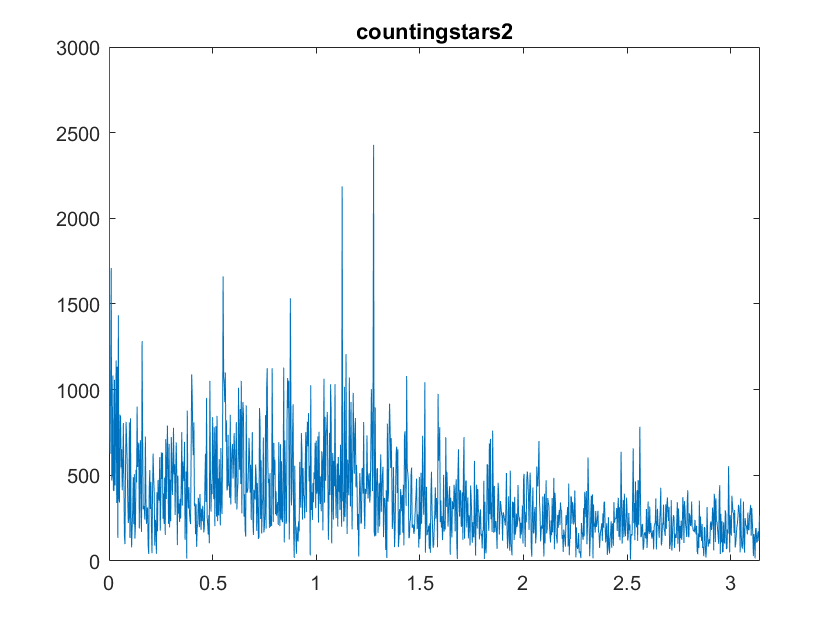

plot_fft("countingstars2");

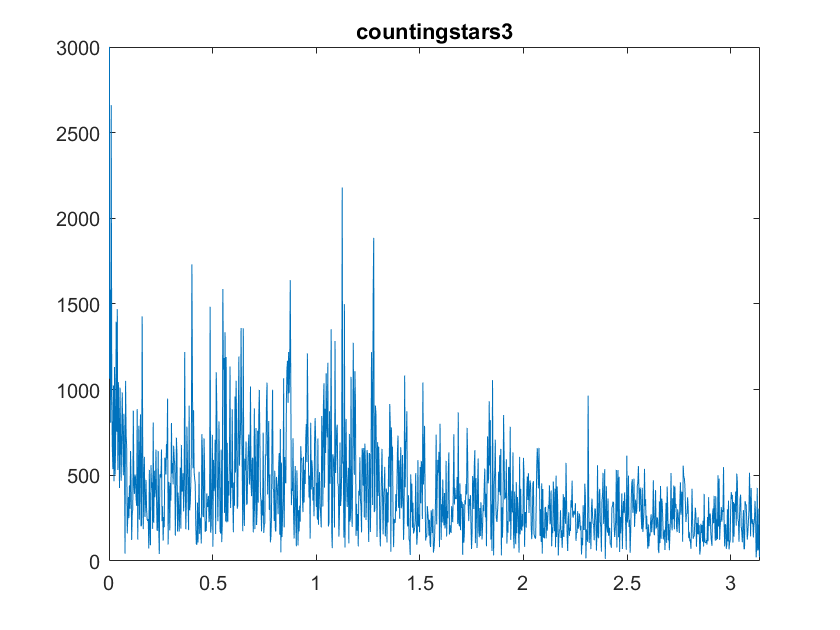

plot_fft("countingstars3");

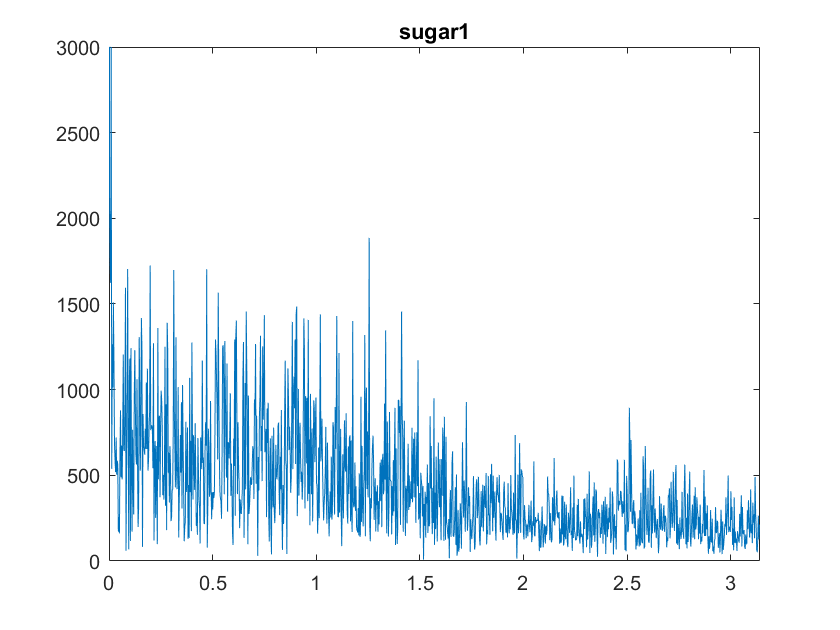

plot_fft("sugar1");

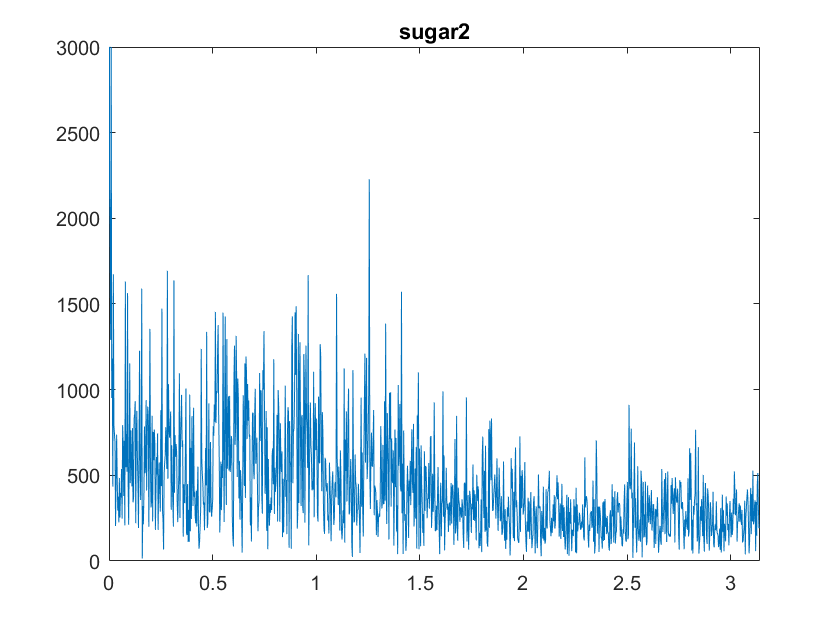

plot_fft("sugar2");

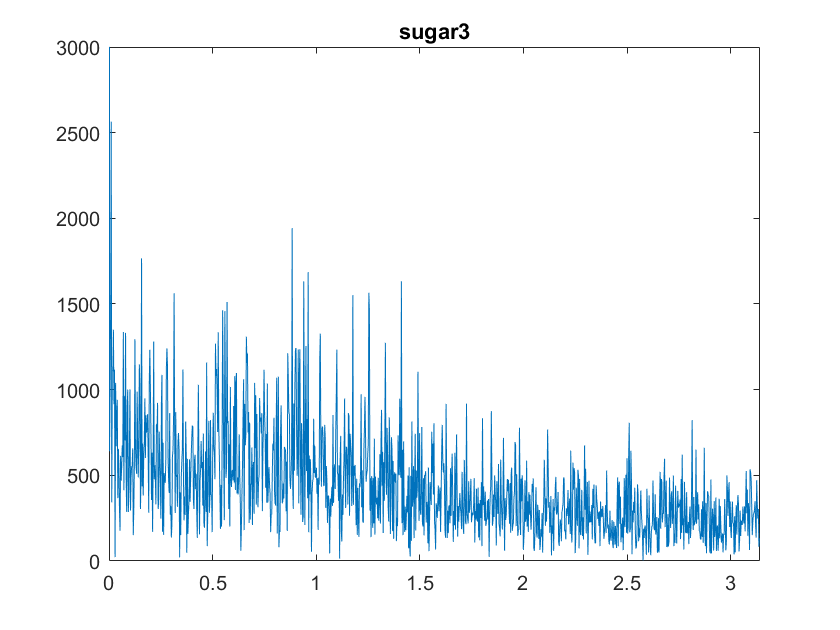

plot_fft("sugar3");

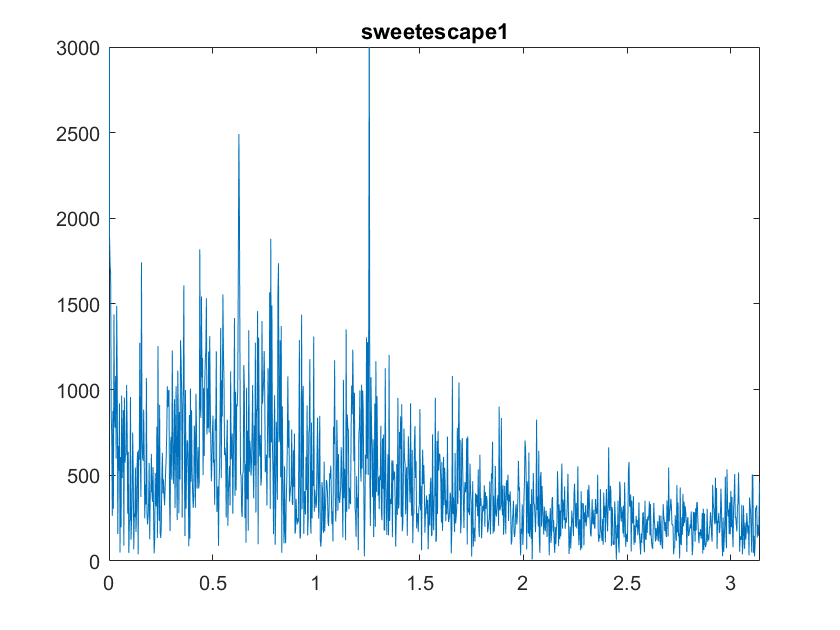

plot_fft("sweetescape1");

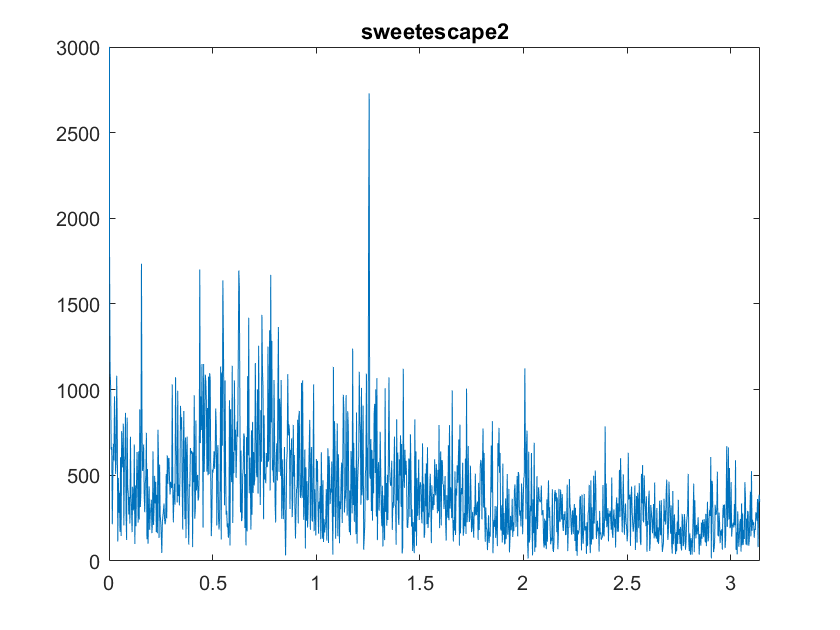

plot_fft("sweetescape2");

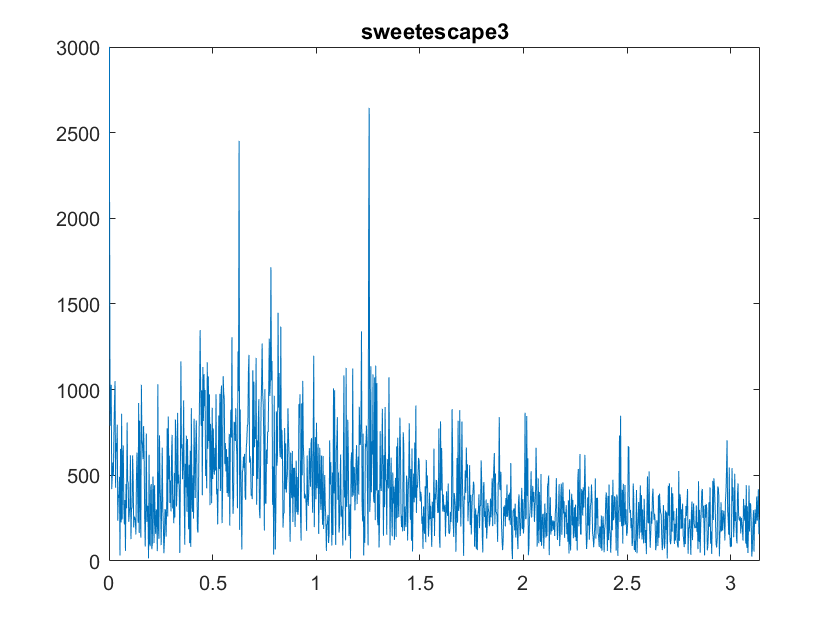

plot_fft("sweetescape3");

function transform = plot_fft(filename)
    load("data/" + filename + ".mat")
    accel = sqrt(Acceleration.X .^ 2 + Acceleration.Y .^ 2 + Acceleration.Z .^ 2) - 9.8;
    trans = fftshift(fft(accel));
    mid = floor(length(trans) / 2);
    transform = trans(mid:end);
    N = length(accel);
    freq = linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
    plot(freq(mid:end), abs(transform));
    title(filename)
    ylim([0, 3000])
    xlim([0, pi])
end